# Lab B Prelab: Introduction to Algebraic Graph Theory

## Part 1: Review of Node-Edge Incidence Matrix

It is suggested that you review the MLX/PDF file for lab 1 about the definition of the **node-edge incidence matrix**. Given a simple, directed, connected and finite graph $G$ with $n$ nodes and $m$ edges, the node-edge incidence matrix $A$ is an $n \times m$ matrix whose entries are either $1, -1$, or $0$. In general, $m \geq n-1$, and $\mathrm{rank}(A) = n-1$. Please make sure you remember how to construct the $A$ matrix given a graph before moving on to the next part of the prelab.

## Part 2: Edge Weights in a Graph

Recall that we gave each edge in the graph examples a lable $e_i$ for the $i$-th edge, and we mentioned a physical interpretation, where an edge is a one-way street from point $a$ to point $b$, ($a,b$ are represented as nodes). Since not all roads are equal (highways, back-alleys, bridges, etc.) and travelling from point $a$ to point $b$ incurs some kind of cost (e.g., toll, fuel needed, and/or duration of travel), a natural question to ask is, *how do we incorporate these costs into a graph model*? 

We achieve this by assigning a positive **weight** to each edge, denoted as $w_i > 0$. Then, since edge $e_i$ has a weight $w_i$, we can conveniently combine all the edge weights into an $m \times 1$ vector as


$$w = \pmatrix{w_1 \cr w_2 \cr \vdots \cr w_m} \in \mathbb{R}^m$$


Alternatively, we can put $w$ on the main diagonal of an $m \times m$ diagonal matrix $W$, where the $i$-th diagonal entry is $w_i$ like so


$$W = \mathrm{diag}(w) = \pmatrix{w_1 & 0 & \cdots & 0 \cr
0 & w_2 & \cdots & 0 \cr 
\vdots & \vdots & \ddots & \vdots & \cr
0 & 0 & \cdots & w_m}.$$


Both $w$ and $W$ describes the edge weights in a graph $G$, and we will use the matrix $W$ in the next section in the spirit of our discussion, which is on *graph matrices*. 

### Example

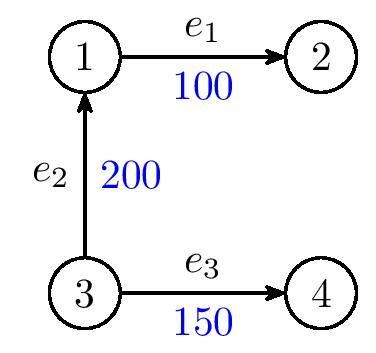

Here, $e_1$ is associated with a weight of $100$, $e_2$ is associated with a weight of $200$, and $e_3$ is associated with a weight of $150$. Thus, the edge weight matrix $W$ can be constructed as 


$$W = \pmatrix{100 & 0 & 0 \cr 0 & 200 & 0 \cr 0 & 0 & 150}.$$


## Part 3 Weighted Node-Edge Incidence Matrix

Now, we can incorporate the edge weights into the node-edge incidence matrix $A$ so that it also contains the information of edge weights. It is extremely simple to do: denote the **weighted node-edge incidence matrix** as $\bar{A}$ (pronounced as "A bar"), and we can construct it as $\bar{A} = AW$. Note that this matrix multiplication is consistent, since $A$ is $n \times m$ and $W$ is $m \times m$. In particular, similar to how we constructed $A$ element-wise, we can also say the following: for every edge $e_k = (i, j)$,

- If $e_k$ **leaves** node $i$ and has edge weight $w_k$, then $\bar{A}_{ik} = w_k$, and $\bar{A}_{jk} = -w_k$,

- If $e_k$ **enters** node $i$ and has edge weight $w_k$, then $\bar{A}_{ik} = -w_k$, and $\bar{A}_{jk} = w_k$.

### Example

In the graph above, we can compute that 


$$\bar{A} = AW = \pmatrix{1 & -1 & 0 \cr -1 & 0  & 0 \cr 0 & 1 & 1 \cr 0 & 0 & -1}\pmatrix{100 & 0 & 0 \cr 0 & 200 & 0 \cr 0 & 0 & 150} = \pmatrix{100 & -200 & 0 \cr -100 & 0 & 0 \cr 0 & 200 & 150 \cr 0 & 0 & -150}$$


Note that the the rows of $\bar{A}$ still describe the nodes in the graph, and the columns of $\bar{A}$ still describe the edges, *but now contain the edge weights*. 

## Part 4 Cycles in a Graph

The cycles are a specific type of sequence of edges that start and end at the same node. In the circuit analysis examples in Topic 1, we have already encountered the notion of cycles in a circuit, which is an application of cycles in a graph. 

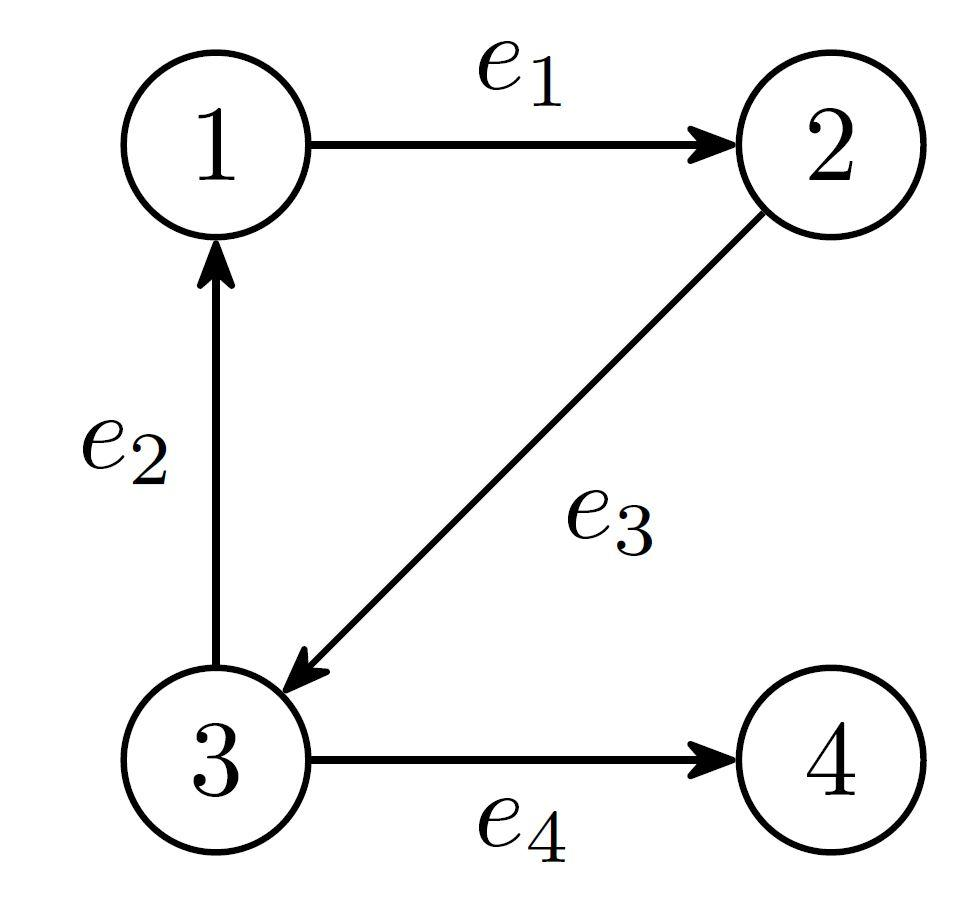

In the graph above, we can observe that the sequence of edges $\{e_1, e_3, e_2\}$ forms a cycle, since it starts at node $1$ and ends at the same node. Alternatively, we can say the sequence $\{e_2, e_1, e_3\}$ is a cycle as well, since it starts at node $2$ and ends there as well, and similarly for the sequence $\{e_3, e_2, e_1\}$. 

Note that in the above example, the direction of the cycle follows the directions of the edges, which is clockwise. But this does not need to always be the case! We can pick our cycle's direction to be **counterclockwise** - then starting at node $1$, the sequence would be $\{-e_2, -e_3, -e_1\}$, that is, the directions of the edges $e_1, e_2, e_3$ are **opposite** to the direction of the cycle. This is a little abuse of notation, but if we expand out the $e_i$ in terms of the node-tuples, then it would make more sense:

- The clockwise cycle is $\{e_1, e_3, e_2\} = \{(1,2), (2,3), (3,1)\}$

- The counterclockwise cycle represented as $\{-e_2, -e_3, -e_1\}$ is actually $\{(1,3), (3,2), (2,1)\}$.

Also note that in the graph above, node $4$ is never part of a cycle. 

## Part 5: A Quick Introduction to Symbolic Variables

So far onn MATLAB, you have been working with numeric values such as decimal numbers, integers, matrices and vectors of real numbers. However, we can also represent the unknown variables **symbolically** on MATLAB, and work directly with *formulas*. For example, it can be useful when you want to take the derivative of a function. 

With the following command, we can create three unknown symbolic variables $x_1, x_2$ and $x_3$:

syms x1 x2 x3

We can further restrict what type of variables they can represent: for example, if we want them to only represent *real numbers*, then we can do the following 

syms x1 x2 x3 real

You can a lot more with symbolic variables, for example, create a matrix with *mixed* symbolic variables and numeric values:

A = [1 2 -1; 
	x1 x2 3; 
	0 2 x3]

$$A = \left(\begin{array}{ccc} 1 & 2 & -1\\ x_{1} & x_{2} & 3\\ 0 & 2 & x_{3} \end{array}\right)$$

Run the commands above to see what results you get. 

Symbolic variables won't be a focus of this topic, but we encourage you to check out some relevant information on them:

- [Create symbolic variables, expressions, functions, matrices - MATLAB sym (mathworks.com)](https://www.mathworks.com/help/symbolic/sym.html)

- [What are symbolic variables? - MATLAB Answers - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/answers/320690-what-are-symbolic-variables)

- [Matlab - Symbolic Math (utah.edu)](https://www.cs.utah.edu/~germain/PPS/Topics/Matlab/symbolic_math.html)